# Create and Customize Wordclouds

`wordcloud` creates a chart of varying sizes of words contained in a provided table.

### Read Collection of Sonnets

We will use a table of words contained in sonnets to demonstrate how to create and customize wordcloud charts. The data file contains a table with a list of words in each row of a table and the number of times they appear in a selection of sonnets.

load sonnetsTable

### Basic Wordcloud Chart

Plot a wordcloud of the data by specifying the table section with the list of words and the counts for each word. A chart will be generated that scales each word's size depending on how frequently it occurs in the dataset.

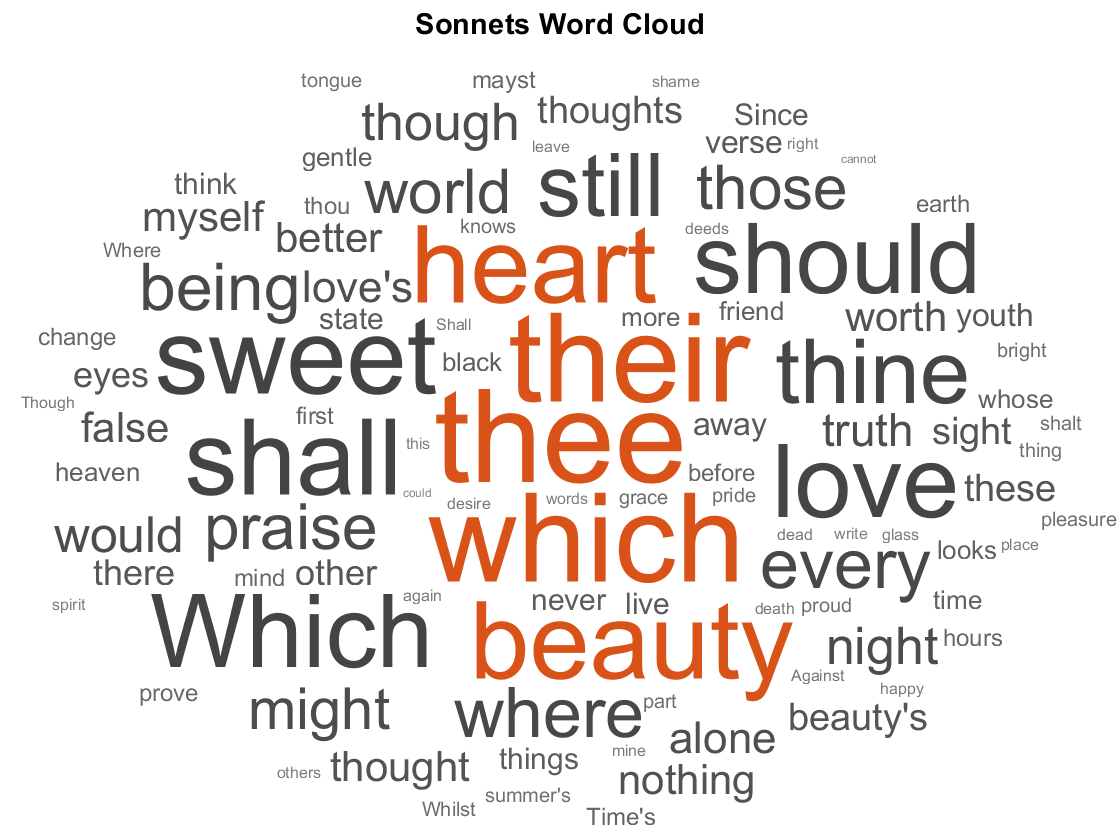

wordcloud(tbl,'Word','Count');
title("Sonnets Word Cloud")

## Customization

### Generate Wordcloud From a String

If the text has not been formatted into the table used in the earlier example, the following approach is necessary to create a word cloud. A list of words is extracted from the text by splitting the string into individual words. The list of words is made into a categorical array `C` which can be read and plotted by `wordcloud`.

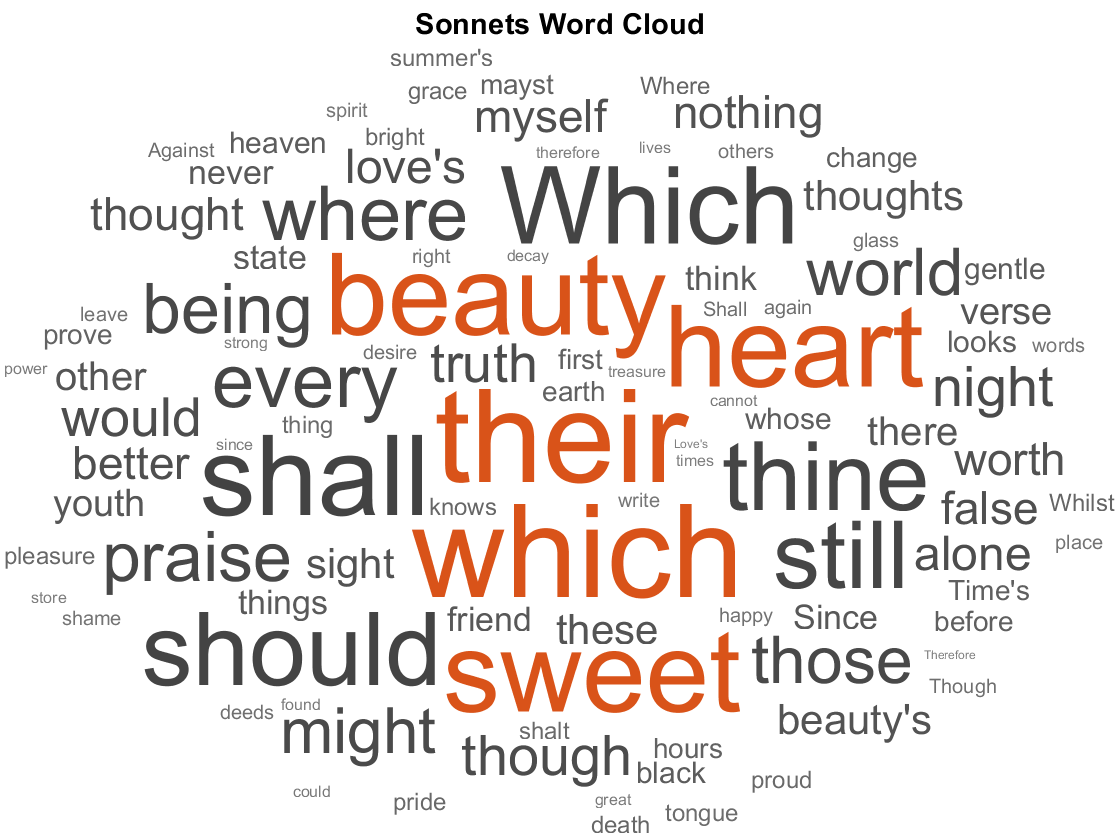

sonnets = string(fileread('sonnets.txt'));
words = extractWords(sonnets);                % call helper function to split the string
C = categorical(words);                       % convert list into a categorical object
wordcloud(C);
title("Sonnets Word Cloud")

### Specify Word Colors

We can specify the color for each word by providing a vector of RGB the same size as the list of words. Each word will be assigned the corresponding color.

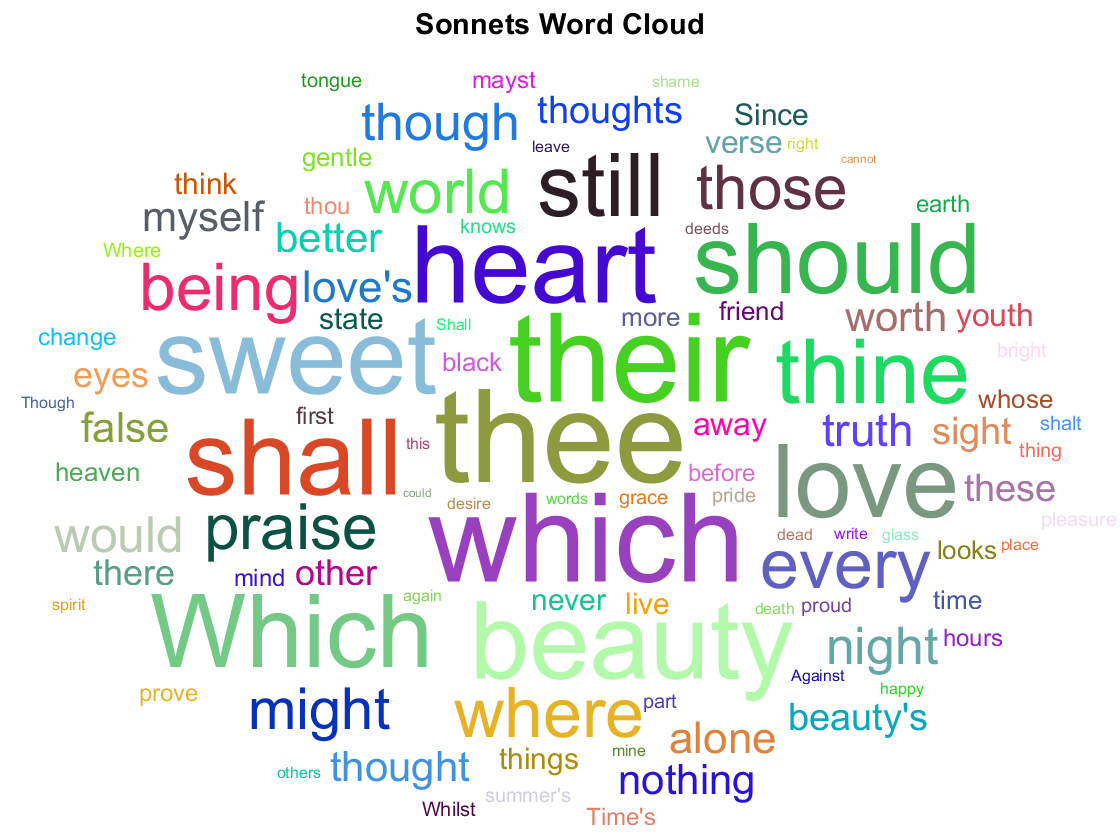

numWords = height(tbl);
colors = rand(numWords,3);
wc = wordcloud(tbl,'Word','Count',...
                   'Color',colors);        % specify the color property 
title("Sonnets Word Cloud")

## Additional Information

### Get All Wordcloud Properties

Graphics objects in MATLAB have many properties. To see all the properties of a wordcloud, uncomment the following code

% get(wc)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[wordcloud](https://www.mathworks.com/help/matlab/ref/wordcloud.html)

### Text Processing Function

This function takes a text string and splits up each individual word, returning them as a list. It can be used for creating a wordcloud from standalone text.

function words = extractWords(text)
    punctuationCharacters = ["." "?" "!" "," ";" ":"];
    text = replace(text,punctuationCharacters," ");
    words = split(join(text));
    words(strlength(words)<5) = [];
end